# Newton1D

function [xs,ys,converged]=newton1d(f,dfdx,x0,N,tol,d_range)
    n=1;
    xs=zeros(1,N+1);
    ys=zeros(1,N+1);
    last_d = dfdx(x0);

    xs(1)=x0;
    ys(1)=f(x0);

    % n-1 = index of last computed x,y,dfdx
    % n = index in array of last computed x,y,dfdx = size of array
    % n = num of step about to start

    while n<=N
        if abs(last_d) < d_range
            error("dfdx ~ 0 at (%d, %d)",xs(n),ys(n));
        end
        new_x = xs(n)-ys(n)/last_d;
        xs(n+1) = new_x;
        ys(n+1) = f(new_x);
        last_d = dfdx(new_x);
        n=n+1;
        
        if abs(xs(n)-xs(n-1))<tol*(1+abs(xs(n)))
            converged = true;
            break;
        end
    end

    xs = xs(1:n);
    ys = ys(1:n);
end

## Plot

function plot_function(ax,f,xmin,xmax)
    range = xmax-xmin;
    density = 100;
    x = linspace(xmin,xmax,range*density);
    y = arrayfun(f,x);
    plot(ax,x,y,'-b');
end

function plot_iteration(ax,xs,ys)
    n=length(xs);
    for i=1:(n-1)
        if i==1
            scatter(ax,xs(1),0,'.r');
        else
            scatter(ax,xs(i),0,'.k');
        end
        plot(ax,[xs(i) xs(i)],[ys(i) 0],'--k');
        plot(ax,[xs(i) xs(i+1)],[ys(i) 0],'-k');
    end
    scatter(ax,xs(n),ys(n),'.g');
end

function [converged, m] = plot_newton1d(ax,f,dfdx,x0,N,tol,d_range)
    [xs,ys,converged] = newton1d(f,dfdx,x0,N,tol,d_range);
    xmin = min(xs)-abs(min(xs))*0.2;
    xmax = max(xs)+abs(max(xs))*0.2;
    plot_function(ax,f,xmin,xmax);
    plot_iteration(ax,xs,ys);
    m = xs(end);
end

function update_plot(ax,ans_lbl,converged_lbl,f,dfdx,x0,N,tol,d_range)
    cla(ax); 
    hold(ax,'on');

    [converged,m] = plot_newton1d(ax,f,dfdx,x0,N,tol,d_range);

    ans_lbl.Text = "Ans: "+num2str(m);
    if converged
        converged_lbl.Text="Converged";
    else
        converged_lbl.Text="Not converged";
    end

    grid(ax, 'on');
    hold(ax, 'off');
end

## Driver

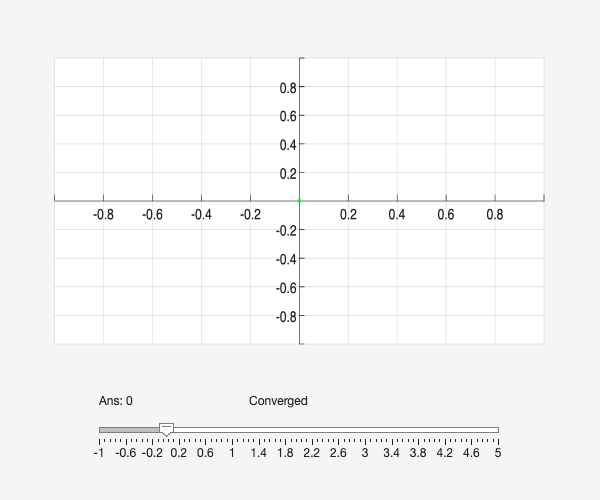

lambda = 2;
f = @(x) exp(lambda*(x-1))-x;
f = @(x) x.^3+x;
dfdx = @(x) lambda*exp(lambda*(x-1))-1;
dfdx = @(x) 3.*x.^2.+1;
N = 1000;
tol = 3e-16;
d_range = 1e-12;

fig = uifigure('Name', 'Newton 1D', 'Position', [100 100 600 500]);

ax = uiaxes(fig, 'Position', [50 150 500 300]); 
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
grid(ax, 'on');

ans_lbl = uilabel(fig, 'Position', [100 100 100 22]); 
ans_lbl.Text="";

converged_lbl = uilabel(fig,'Position',[250 100 100 22]);
converged_lbl.Text="";

sld = uislider(fig, 'Position', [100 80 400 3]); 
sld.Limits = [-1 5];
sld.Value = 0;
sld.ValueChangingFcn = @(src, event) update_plot(ax,ans_lbl,converged_lbl,f,dfdx,event.Value,N,tol,d_range);


update_plot(ax,ans_lbl,converged_lbl,f,dfdx,0,N,tol,d_range);